## Exercise 1 (using Newton - Euler algorithm)

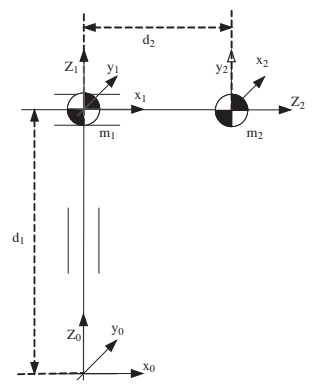

Note: S1 should be orientated as S2

syms g d1 d1_dot d1_ddot d2 d2_dot d2_ddot m1 m2

% Initial conditions
w00 = [0 0 0].';
w00_dot = [0 0 0].';
v00 = [0 0 0].';
v00_dot = [0 0 g].';
z0 = [0 0 1].';
p11 = [0 d1*cos(90) d1*sin(90)].';
s11 = [0 0 0].';
p22 = [0 d2*cos(0) d2*sin(0)].';
s22 = [0 0 0].';

% Rotational Matrixes
R01 = rotz(90) * rotx(90)

R01 =      0     0     1
     1     0     0
     0     1     0


R10 = R01.'

R10 =      0     1     0
     0     0     1
     1     0     0


R12 = eye(3)

R12 =      1     0     0
     0     1     0
     0     0     1


R21 = R12.'

R21 =      1     0     0
     0     1     0
     0     0     1


R02 = R01 * R12

R02 =      0     0     1
     1     0     0
     0     1     0


R20 = R02.'

R20 =      0     1     0
     0     0     1
     1     0     0


% Angular velocity
w11 = R10 * w00

w11 =      0
     0
     0


w22 = R21 * w11

w22 =      0
     0
     0


% Angular acceleration
w11_dot = R10 * w00_dot

w11_dot =      0
     0
     0


w22_dot = R21 * w11_dot

w22_dot =      0
     0
     0


% Linear acceleration
v11_dot = R10 * (z0 * d1_ddot + v00_dot) + cross(w11, p11) + cross(2*w11, R10*z0*d1_dot) + cross(w11, cross(w11, p11))

$$v11\_dot = \left(\begin{array}{c} 0\\ d_{\ddot{1}}+g\\ 0 \end{array}\right)$$

v22_dot = R21 * (z0 * d2_ddot + v11_dot) + cross(w22, p22) + cross(2*w22, R21*z0*d2_dot) + cross(w22, cross(w22, p22))

$$v22\_dot = \left(\begin{array}{c} 0\\ d_{\ddot{1}}+g\\ d_{\ddot{2}} \end{array}\right)$$

% Center of gravity's acceleration
a11 = cross(w11_dot, s11) + cross(w11, cross(w11, s11)) + v11_dot

$$a11 = \left(\begin{array}{c} 0\\ d_{\ddot{1}}+g\\ 0 \end{array}\right)$$

a22 = cross(w22_dot, s22) + cross(w22, cross(w22, s22)) + v22_dot

$$a22 = \left(\begin{array}{c} 0\\ d_{\ddot{1}}+g\\ d_{\ddot{2}} \end{array}\right)$$

% Forces
f33 = [0 0 0].';
R23 = eye(3);

f22 = R23 * f33 + m2 * a22

$$f22 = \left(\begin{array}{c} 0\\ m_{2}\,\left(d_{\ddot{1}}+g\right)\\ d_{\ddot{2}}\,m_{2} \end{array}\right)$$

f11 = R12 * f22 + m1 * a11

$$f11 = \left(\begin{array}{c} 0\\ m_{1}\,\left(d_{\ddot{1}}+g\right)+m_{2}\,\left(d_{\ddot{1}}+g\right)\\ d_{\ddot{2}}\,m_{2} \end{array}\right)$$

% Torques (skipped since there are only pristatic movement)
% Tau
tau1 = f11.' * R10 * z0

$$tau1 = m_{1}\,\left(d_{\ddot{1}}+g\right)+m_{2}\,\left(d_{\ddot{1}}+g\right)$$

tau2 = f22.' * R21 * z0

$$tau2 = d_{\ddot{2}}\,m_{2}$$

## Exercise 2 (using Langrange algorithm)

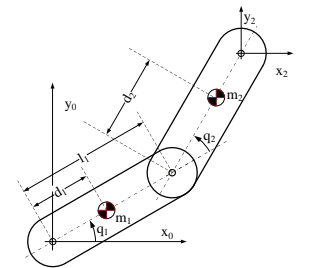

syms q1 q1_dot q1_ddot q2 q2_dot q2_ddot d1 d2 l1 l2 m1 m2

% Forming all HTMs
p = [l1*cos(q1) l1*sin(q1) 0].';
T = HTM(eye(3), p);

A01 = T

$$A01 = \left(\begin{array}{cccc} 1 & 0 & 0 & l_{1}\,\cos\left(q_{1}\right)\\ 0 & 1 & 0 & l_{1}\,\sin\left(q_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

p = [l2*cos(q1 + q2) l2*sin(q1 + q2) 0].';
T = HTM(eye(3), p);

A12 = T

$$A12 = \left(\begin{array}{cccc} 1 & 0 & 0 & l_{2}\,\cos\left(q_{1}+q_{2}\right)\\ 0 & 1 & 0 & l_{2}\,\sin\left(q_{1}+q_{2}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A02 = simplify(A01 * A12)

$$A02 = \left(\begin{array}{cccc} 1 & 0 & 0 & l_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)\\ 0 & 1 & 0 & l_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

% Solving for all Uij
QR = [0 -1 0 0; 1 0 0 0; 0 0 0 0; 0 0 0 0];   % Rotational Q
Qp = [0 0 0 0; 0 0 0 0; 0 0 0 1; 0 0 0 0];    % Traslational Q
Aii = HTM(eye(3));                            % HTM from i to i

U11 = simplify(Aii * QR * A01)

$$U11 = \left(\begin{array}{cccc} 0 & -1 & 0 & -l_{1}\,\sin\left(q_{1}\right)\\ 1 & 0 & 0 & l_{1}\,\cos\left(q_{1}\right)\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

U12 = 0;
U21 = simplify(Aii * QR * A02)

$$U21 = \left(\begin{array}{cccc} 0 & -1 & 0 & -l_{2}\,\sin\left(q_{1}+q_{2}\right)-l_{1}\,\sin\left(q_{1}\right)\\ 1 & 0 & 0 & l_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

U22 = simplify(A01 * QR * A12)

$$U22 = \left(\begin{array}{cccc} 0 & -1 & 0 & -l_{2}\,\sin\left(q_{1}+q_{2}\right)\\ 1 & 0 & 0 & l_{2}\,\cos\left(q_{1}+q_{2}\right)\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

% Solving for all Uijk
U111 = Aii * QR * Aii * QR * A01

$$U111 = \left(\begin{array}{cccc} -1 & 0 & 0 & -l_{1}\,\cos\left(q_{1}\right)\\ 0 & -1 & 0 & -l_{1}\,\sin\left(q_{1}\right)\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

U112 = 0;
U121 = 0;
U122 = 0;
U211 = Aii * QR * Aii * QR * A02

$$U211 = \left(\begin{array}{cccc} -1 & 0 & 0 & -l_{2}\,\cos\left(q_{1}+q_{2}\right)-l_{1}\,\cos\left(q_{1}\right)\\ 0 & -1 & 0 & -l_{2}\,\sin\left(q_{1}+q_{2}\right)-l_{1}\,\sin\left(q_{1}\right)\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

U212 = simplify(Aii * QR * A01 * QR * A12)

$$U212 = \left(\begin{array}{cccc} -1 & 0 & 0 & -l_{2}\,\cos\left(q_{1}+q_{2}\right)\\ 0 & -1 & 0 & -l_{2}\,\sin\left(q_{1}+q_{2}\right)\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

U221 = simplify(Aii * QR * A01 * QR * A12)

$$U221 = \left(\begin{array}{cccc} -1 & 0 & 0 & -l_{2}\,\cos\left(q_{1}+q_{2}\right)\\ 0 & -1 & 0 & -l_{2}\,\sin\left(q_{1}+q_{2}\right)\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

U222 = simplify(A01 * QR * Aii * QR * A12)

$$U222 = \left(\begin{array}{cccc} -1 & 0 & 0 & -l_{2}\,\cos\left(q_{1}+q_{2}\right)\\ 0 & -1 & 0 & -l_{2}\,\sin\left(q_{1}+q_{2}\right)\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

% Solving for pseudoinertias Ji
x1 = d1 * cos(q1);
y1 = d1 * sin(q1);
z1 = 0;
J1 = simplify([int(x1^2, m1) int(x1 * y1, m1) int(x1 * z1, m1) int(x1, m1); ...
      int(y1 * x1, m1) int(y1^2, m1) int(y1 * z1, m1) int(y1, m1); ...
      int(z1 * x1, m1) int(z1 * y1, m1) int(z1^2, m1) int(z1, m1); ...
      int(x1, m1) int(y1, m1) int(z1, m1) int(1, m1)])

$$J1 = \begin{array}{l} \left(\begin{array}{cccc} {d_{1}}^{2}\,m_{1}\,{\cos\left(q_{1}\right)}^{2} & \sigma_{1} & 0 & d_{1}\,m_{1}\,\cos\left(q_{1}\right)\\ \sigma_{1} & {d_{1}}^{2}\,m_{1}\,{\sin\left(q_{1}\right)}^{2} & 0 & d_{1}\,m_{1}\,\sin\left(q_{1}\right)\\ 0 & 0 & 0 & 0\\ d_{1}\,m_{1}\,\cos\left(q_{1}\right) & d_{1}\,m_{1}\,\sin\left(q_{1}\right) & 0 & m_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{{d_{1}}^{2}\,m_{1}\,\sin\left(2\,q_{1}\right)}{2} \end{array}$$

x2 = d2 * cos(q1 + q2);
y2 = d2 * sin(q1 + q2);
z2 = 0;
J2 = simplify([int(x2^2, m2) int(x2 * y2, m2) int(x2 * z2, m2) int(x2, m2); ...
      int(y2 * x2, m2) int(y2^2, m2) int(y2 * z2, m2) int(y2, m2); ...
      int(z2 * x2, m2) int(z2 * y2, m2) int(z2^2, m2) int(z2, m2); ...
      int(x2, m2) int(y2, m2) int(z2, m2) int(1, m2)])

$$J2 = \begin{array}{l} \left(\begin{array}{cccc} {d_{2}}^{2}\,m_{2}\,{\cos\left(q_{1}+q_{2}\right)}^{2} & \sigma_{1} & 0 & d_{2}\,m_{2}\,\cos\left(q_{1}+q_{2}\right)\\ \sigma_{1} & {d_{2}}^{2}\,m_{2}\,{\sin\left(q_{1}+q_{2}\right)}^{2} & 0 & d_{2}\,m_{2}\,\sin\left(q_{1}+q_{2}\right)\\ 0 & 0 & 0 & 0\\ d_{2}\,m_{2}\,\cos\left(q_{1}+q_{2}\right) & d_{2}\,m_{2}\,\sin\left(q_{1}+q_{2}\right) & 0 & m_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{{d_{2}}^{2}\,m_{2}\,\sin\left(2\,q_{1}+2\,q_{2}\right)}{2} \end{array}$$

% Solving for intertia matrixes D = dij
d11 = simplify(trace(U11 * J1 * U11.' + U21 * J2 * U21.'))

$$d11 = {d_{1}}^{2}\,m_{1}+{d_{2}}^{2}\,m_{2}+{l_{1}}^{2}\,m_{1}+{l_{1}}^{2}\,m_{2}+{l_{2}}^{2}\,m_{2}+2\,d_{1}\,l_{1}\,m_{1}+2\,d_{2}\,l_{2}\,m_{2}+2\,d_{2}\,l_{1}\,m_{2}\,\cos\left(q_{2}\right)+2\,l_{1}\,l_{2}\,m_{2}\,\cos\left(q_{2}\right)$$

d12 = simplify(trace(U22 * J2 * U21.'))

$$d12 = m_{2}\,\left(d_{2}+l_{2}\right)\,\left(d_{2}+l_{2}+l_{1}\,\cos\left(q_{2}\right)\right)$$

d21 = simplify(trace(U21 * J2 * U22.'))

$$d21 = m_{2}\,\left(d_{2}+l_{2}\right)\,\left(d_{2}+l_{2}+l_{1}\,\cos\left(q_{2}\right)\right)$$

d22 = simplify(trace(U22 * J2 * U22.'))

$$d22 = m_{2}\,{\left(d_{2}+l_{2}\right)}^{2}$$

D = [d11 d12; d21 d22]

$$D = \begin{array}{l} \left(\begin{array}{cc} {d_{1}}^{2}\,m_{1}+{d_{2}}^{2}\,m_{2}+{l_{1}}^{2}\,m_{1}+{l_{1}}^{2}\,m_{2}+{l_{2}}^{2}\,m_{2}+2\,d_{1}\,l_{1}\,m_{1}+2\,d_{2}\,l_{2}\,m_{2}+2\,d_{2}\,l_{1}\,m_{2}\,\cos\left(q_{2}\right)+2\,l_{1}\,l_{2}\,m_{2}\,\cos\left(q_{2}\right) & \sigma_{1}\\ \sigma_{1} & m_{2}\,{\left(d_{2}+l_{2}\right)}^{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=m_{2}\,\left(d_{2}+l_{2}\right)\,\left(d_{2}+l_{2}+l_{1}\,\cos\left(q_{2}\right)\right) \end{array}$$

% Solving for hijm
h111 = simplify(trace(U111 * J1 * U11.' + U211 * J2 * U21.'))

$$h111 = 0$$

h112 = simplify(trace(U212 * J2 * U21.'))

$$h112 = -l_{1}\,m_{2}\,\sin\left(q_{2}\right)\,\left(d_{2}+l_{2}\right)$$

h121 = simplify(trace(U221 * J2 * U21.'))

$$h121 = -l_{1}\,m_{2}\,\sin\left(q_{2}\right)\,\left(d_{2}+l_{2}\right)$$

h122 = simplify(trace(U222 * J2 * U21.'))

$$h122 = -l_{1}\,m_{2}\,\sin\left(q_{2}\right)\,\left(d_{2}+l_{2}\right)$$

h211 = simplify(trace(U211 * J2 * U22.'))

$$h211 = l_{1}\,m_{2}\,\sin\left(q_{2}\right)\,\left(d_{2}+l_{2}\right)$$

h212 = simplify(trace(U212 * J2 * U22.'))

$$h212 = 0$$

h221 = simplify(trace(U221 * J2 * U22.'))

$$h221 = 0$$

h222 = simplify(trace(U222 * J2 * U22.'))

$$h222 = 0$$

% Solving for H = hi
h1 = h111 * q1_dot * q1_dot + h112 * q1_dot * q2_dot + ...
     h121 * q2_dot * q1_dot + h122 * q2_dot * q2_dot

$$h1 = -l_{1}\,m_{2}\,\sin\left(q_{2}\right)\,\left(d_{2}+l_{2}\right)\,{q_{\dot{2}}}^{2}-2\,l_{1}\,m_{2}\,q_{\dot{1}}\,\sin\left(q_{2}\right)\,\left(d_{2}+l_{2}\right)\,q_{\dot{2}}$$

h2 = h211 * q1_dot * q1_dot + h212 * q1_dot * q2_dot + ...
     h221 * q2_dot * q1_dot + h222 * q2_dot * q2_dot

$$h2 = l_{1}\,m_{2}\,{q_{\dot{1}}}^{2}\,\sin\left(q_{2}\right)\,\left(d_{2}+l_{2}\right)$$

H = [h1; h2]

$$H = \left(\begin{array}{c} -l_{1}\,m_{2}\,\sin\left(q_{2}\right)\,\left(d_{2}+l_{2}\right)\,{q_{\dot{2}}}^{2}-2\,l_{1}\,m_{2}\,q_{\dot{1}}\,\sin\left(q_{2}\right)\,\left(d_{2}+l_{2}\right)\,q_{\dot{2}}\\ l_{1}\,m_{2}\,{q_{\dot{1}}}^{2}\,\sin\left(q_{2}\right)\,\left(d_{2}+l_{2}\right) \end{array}\right)$$

% Solving C = ci
G = [0 -g 0 0];
r11 = [d1*cos(q1) d1*sin(q1) 0 1].';
r22 = [d2*cos(q1 + q2) d2*sin(q1 + q2) 0 1].';

c1 = -m1 * G * U11 * r11 + -m2 * G * U21 * r22

$$c1 = g\,m_{2}\,\left(l_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)\right)+d_{2}\,g\,m_{2}\,\cos\left(q_{1}+q_{2}\right)+d_{1}\,g\,m_{1}\,\cos\left(q_{1}\right)+g\,l_{1}\,m_{1}\,\cos\left(q_{1}\right)$$

c2 = -m1 * G * U12 * r11 + -m2 * G * U22 * r22

$$c2 = d_{2}\,g\,m_{2}\,\cos\left(q_{1}+q_{2}\right)+g\,l_{2}\,m_{2}\,\cos\left(q_{1}+q_{2}\right)$$

C = [c1; c2]

$$C = \left(\begin{array}{c} g\,m_{2}\,\left(l_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)\right)+d_{2}\,g\,m_{2}\,\cos\left(q_{1}+q_{2}\right)+d_{1}\,g\,m_{1}\,\cos\left(q_{1}\right)+g\,l_{1}\,m_{1}\,\cos\left(q_{1}\right)\\ d_{2}\,g\,m_{2}\,\cos\left(q_{1}+q_{2}\right)+g\,l_{2}\,m_{2}\,\cos\left(q_{1}+q_{2}\right) \end{array}\right)$$

% Completing system's dynamic equation
q_ddot = [q1_ddot; q2_ddot];
tau = simplify(D * q_ddot + H + C)

$$tau = \left(\begin{array}{c} -l_{1}\,m_{2}\,\sin\left(q_{2}\right)\,\left(d_{2}+l_{2}\right)\,{q_{\dot{2}}}^{2}-2\,l_{1}\,m_{2}\,q_{\dot{1}}\,\sin\left(q_{2}\right)\,\left(d_{2}+l_{2}\right)\,q_{\dot{2}}+q_{\ddot{1}}\,\left({d_{1}}^{2}\,m_{1}+{d_{2}}^{2}\,m_{2}+{l_{1}}^{2}\,m_{1}+{l_{1}}^{2}\,m_{2}+{l_{2}}^{2}\,m_{2}+2\,d_{1}\,l_{1}\,m_{1}+2\,d_{2}\,l_{2}\,m_{2}+2\,d_{2}\,l_{1}\,m_{2}\,\cos\left(q_{2}\right)+2\,l_{1}\,l_{2}\,m_{2}\,\cos\left(q_{2}\right)\right)+g\,m_{2}\,\left(l_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)\right)+m_{2}\,q_{\ddot{2}}\,\left(d_{2}+l_{2}\right)\,\left(d_{2}+l_{2}+l_{1}\,\cos\left(q_{2}\right)\right)+d_{2}\,g\,m_{2}\,\cos\left(q_{1}+q_{2}\right)+d_{1}\,g\,m_{1}\,\cos\left(q_{1}\right)+g\,l_{1}\,m_{1}\,\cos\left(q_{1}\right)\\ m_{2}\,\left(d_{2}+l_{2}\right)\,\left(l_{1}\,\sin\left(q_{2}\right)\,{q_{\dot{1}}}^{2}+d_{2}\,q_{\ddot{1}}+d_{2}\,q_{\ddot{2}}+l_{2}\,q_{\ddot{1}}+l_{2}\,q_{\ddot{2}}+g\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,q_{\ddot{1}}\,\cos\left(q_{2}\right)\right) \end{array}\right)$$

T1 = tau(1)

$$T1 = -l_{1}\,m_{2}\,\sin\left(q_{2}\right)\,\left(d_{2}+l_{2}\right)\,{q_{\dot{2}}}^{2}-2\,l_{1}\,m_{2}\,q_{\dot{1}}\,\sin\left(q_{2}\right)\,\left(d_{2}+l_{2}\right)\,q_{\dot{2}}+q_{\ddot{1}}\,\left({d_{1}}^{2}\,m_{1}+{d_{2}}^{2}\,m_{2}+{l_{1}}^{2}\,m_{1}+{l_{1}}^{2}\,m_{2}+{l_{2}}^{2}\,m_{2}+2\,d_{1}\,l_{1}\,m_{1}+2\,d_{2}\,l_{2}\,m_{2}+2\,d_{2}\,l_{1}\,m_{2}\,\cos\left(q_{2}\right)+2\,l_{1}\,l_{2}\,m_{2}\,\cos\left(q_{2}\right)\right)+g\,m_{2}\,\left(l_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)\right)+m_{2}\,q_{\ddot{2}}\,\left(d_{2}+l_{2}\right)\,\left(d_{2}+l_{2}+l_{1}\,\cos\left(q_{2}\right)\right)+d_{2}\,g\,m_{2}\,\cos\left(q_{1}+q_{2}\right)+d_{1}\,g\,m_{1}\,\cos\left(q_{1}\right)+g\,l_{1}\,m_{1}\,\cos\left(q_{1}\right)$$

T2 = tau(2)

$$T2 = m_{2}\,\left(d_{2}+l_{2}\right)\,\left(l_{1}\,\sin\left(q_{2}\right)\,{q_{\dot{1}}}^{2}+d_{2}\,q_{\ddot{1}}+d_{2}\,q_{\ddot{2}}+l_{2}\,q_{\ddot{1}}+l_{2}\,q_{\ddot{2}}+g\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,q_{\ddot{1}}\,\cos\left(q_{2}\right)\right)$$